# CS229 - Machine Learning

## Project

save('GP Labels - Split Day.mat')

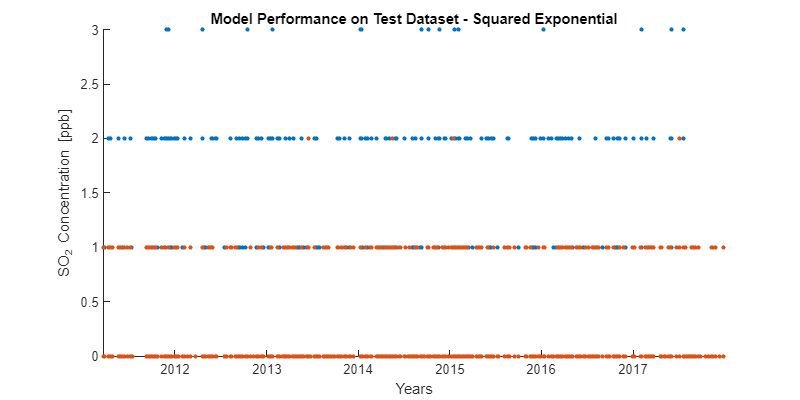

load("GP Labels - Split Day.mat")

close all
clear
clc
warning('off','all')
rng default

### Load Data

% Load Data
Trainning_Data_Table = readtable('Trainning_Data.csv');
Validation_Data_Table = readtable('Validation_Data.csv');
Testing_Data_Table = readtable('Testing_Data.csv');

Trainning_Data = table2array(Trainning_Data_Table);
Validation_Data = table2array(Validation_Data_Table);
Testing_Data = table2array(Testing_Data_Table);

% Use Trainning Data to Train Model
x_train = Trainning_Data(:, [2, 3, 5, 6, 7, 8, 9, 10, 11, 12]);
y_train = Trainning_Data(:, 13);
t_train = datetime(Trainning_Data(:, 1),'ConvertFrom','datenum');
% Use Validation Data to Select Model
x_valid = Validation_Data(:, [2, 3, 5, 6, 7, 8, 9, 10, 11, 12]);
y_valid = Validation_Data(:, 13);
t_valid = datetime(Validation_Data(:, 1),'ConvertFrom','datenum');
% Use Test Data to Evaluate Model
x_test = Testing_Data(:, [2, 3, 5, 6, 7, 8, 9, 10, 11, 12]);
y_test = Testing_Data(:, 13);
t_test = datetime(Testing_Data(:, 1),'ConvertFrom','datenum');

### Train Gaussian Process with Various Kernels

% Fit Gaussian Process with exponential Kernel
gprMdl_1 = fitrgp(x_train, y_train,'KernelFunction','exponential');

% Fit Gaussian Process with squared exponential Kernel
gprMdl_2 = fitrgp(x_train, y_train,'KernelFunction','squaredexponential');

% Fit Gaussian Process with matern32 Kernel
gprMdl_3 = fitrgp(x_train, y_train,'KernelFunction','matern32');

% Fit Gaussian Process with matern52 Kernel
gprMdl_4 = fitrgp(x_train, y_train,'KernelFunction','matern52');

% Fit Gaussian Process with rational quadratic Kernel
gprMdl_5 = fitrgp(x_train, y_train,'KernelFunction','rationalquadratic');

### Predict

% Trainning
% y_train_pred(:,1) = predict(gprMdl_1, x_train);
% y_train_pred(:,2) = predict(gprMdl_2, x_train);
% y_train_pred(:,3) = predict(gprMdl_3, x_train);
% y_train_pred(:,4) = predict(gprMdl_4, x_train);
% y_train_pred(:,5) = predict(gprMdl_5, x_train);

% Validation
y_valid_pred(:,1) = predict(gprMdl_1, x_valid);
y_valid_pred(:,2) = predict(gprMdl_2, x_valid);
y_valid_pred(:,3) = predict(gprMdl_3, x_valid);
y_valid_pred(:,4) = predict(gprMdl_4, x_valid);
y_valid_pred(:,5) = predict(gprMdl_5, x_valid);

% Round to nearest integer
y_valid_pred = round(y_valid_pred);

### Plots for Validation

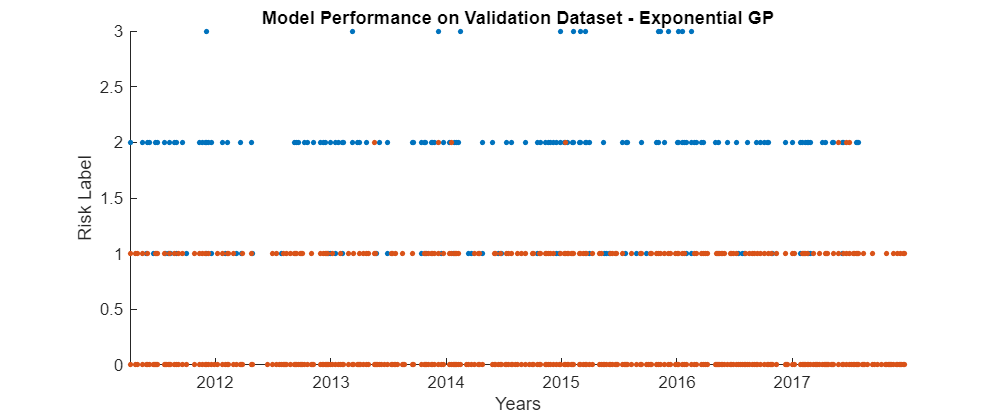

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 1), 10, 'filled')
hold off
ylabel('Risk Label')
xlabel('Years')
title('Model Performance on Validation Dataset - Exponential GP')

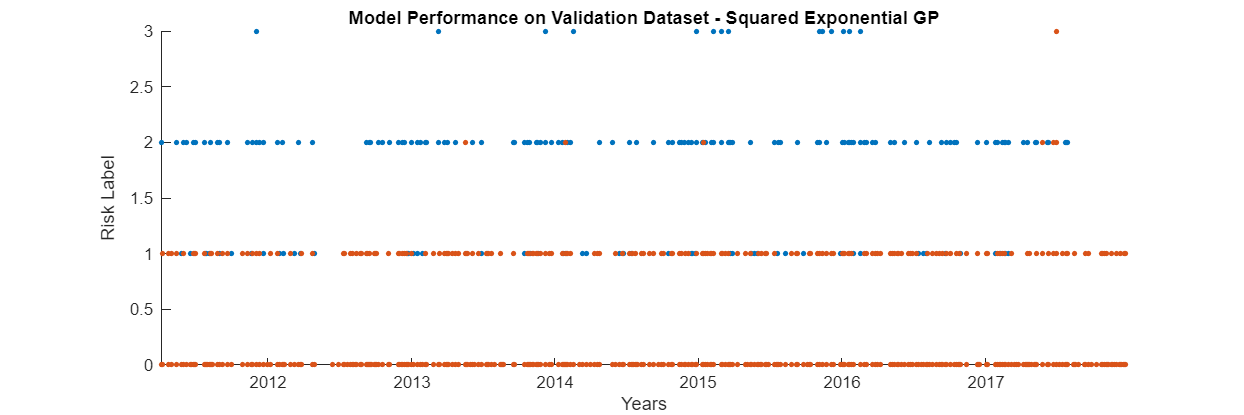

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 2), 10, 'filled')
hold off
ylabel('Risk Label')
xlabel('Years')
title('Model Performance on Validation Dataset - Squared Exponential GP')

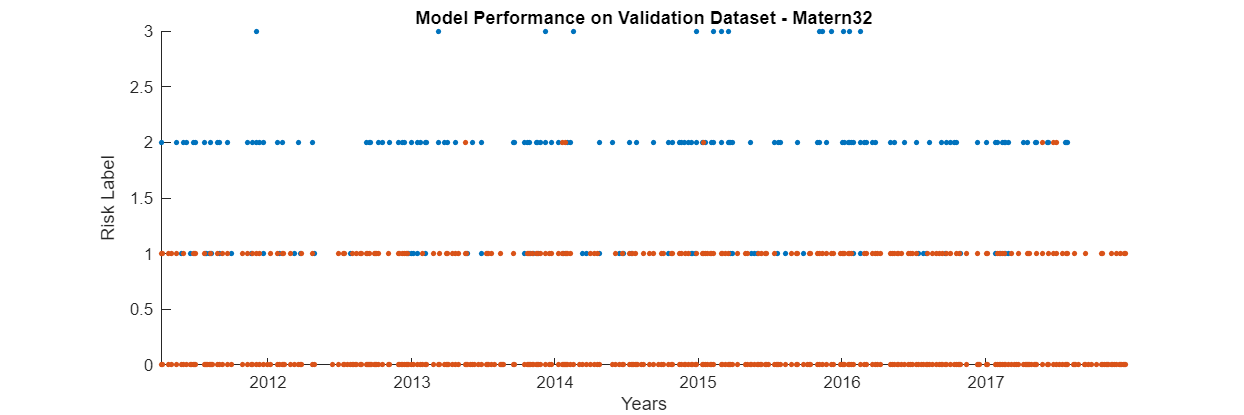

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 3), 10, 'filled')
hold off
ylabel('Risk Label')
xlabel('Years')
title('Model Performance on Validation Dataset - Matern32')

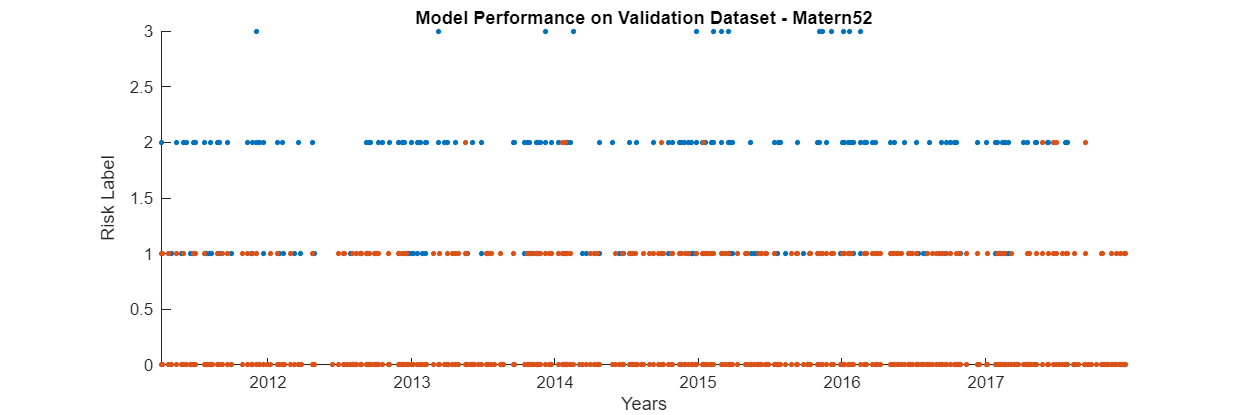

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 4), 10, 'filled')
hold off
ylabel('Risk Label')
xlabel('Years')
title('Model Performance on Validation Dataset - Matern52')

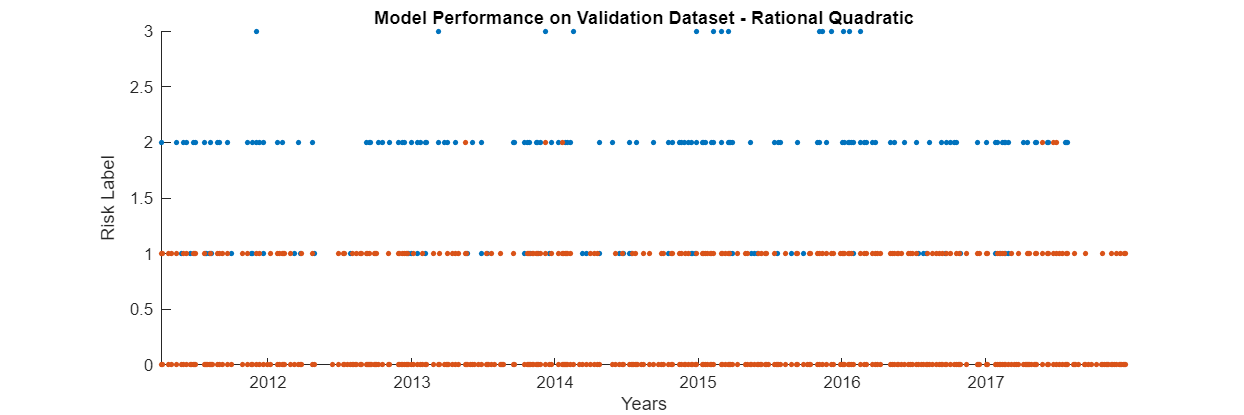

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_valid, y_valid, 10, 'filled')
hold on
scatter(t_valid, y_valid_pred(:, 5), 10, 'filled')
hold off
ylabel('Risk Label')
xlabel('Years')
title('Model Performance on Validation Dataset - Rational Quadratic')

### Plots for Validation - Confussion Charts

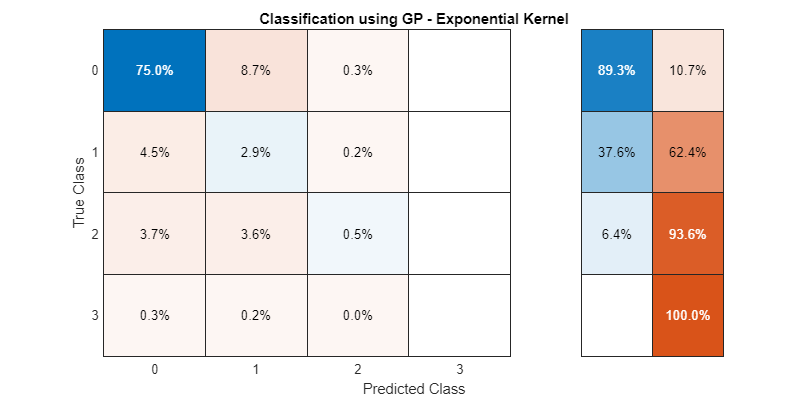

% Plot Confussion Matrix
fig = figure('Position', [0,0,1200,400]);
confusionchart(Validation_Data_Table.Risk_Label, y_valid_pred(:, 1), 'Normalization', 'total-normalized','RowSummary','row-normalized');
title('Classification using GP - Exponential Kernel')

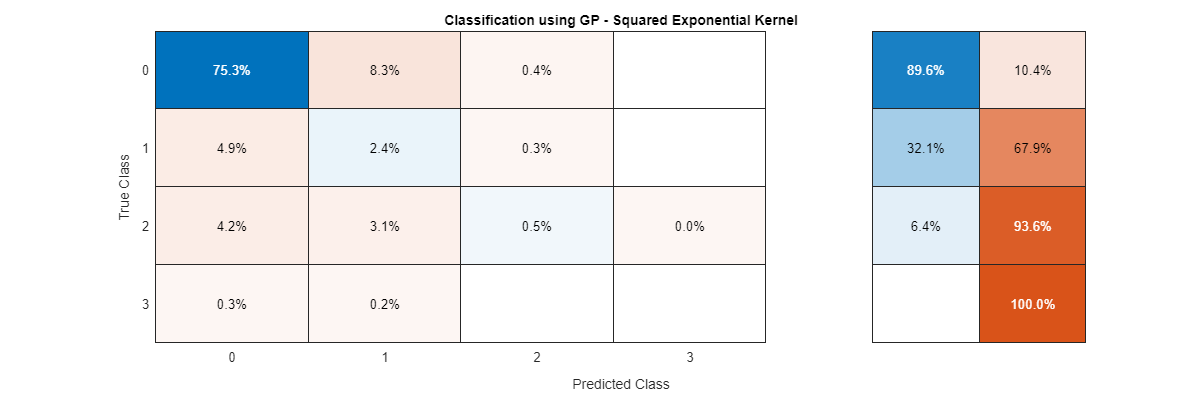

% Plot Confussion Matrix
fig = figure('Position', [0,0,1200,400]);
confusionchart(Validation_Data_Table.Risk_Label, y_valid_pred(:, 2), 'Normalization', 'total-normalized','RowSummary','row-normalized');
title('Classification using GP - Squared Exponential Kernel')

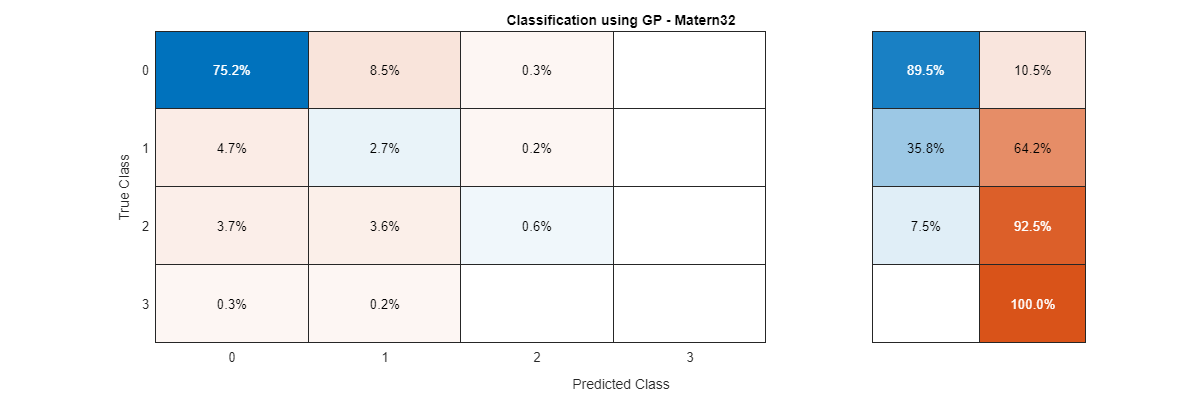

% Plot Confussion Matrix
fig = figure('Position', [0,0,1200,400]);
confusionchart(Validation_Data_Table.Risk_Label, y_valid_pred(:, 3), 'Normalization', 'total-normalized','RowSummary','row-normalized');
title('Classification using GP - Matern32')

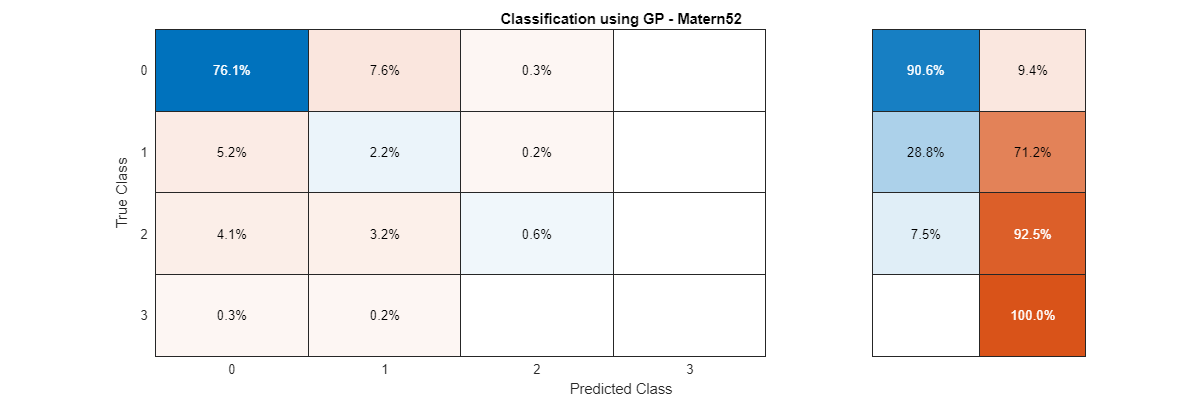

% Plot Confussion Matrix
fig = figure('Position', [0,0,1200,400]);
confusionchart(Validation_Data_Table.Risk_Label, y_valid_pred(:, 4), 'Normalization', 'total-normalized','RowSummary','row-normalized');
title('Classification using GP - Matern52')

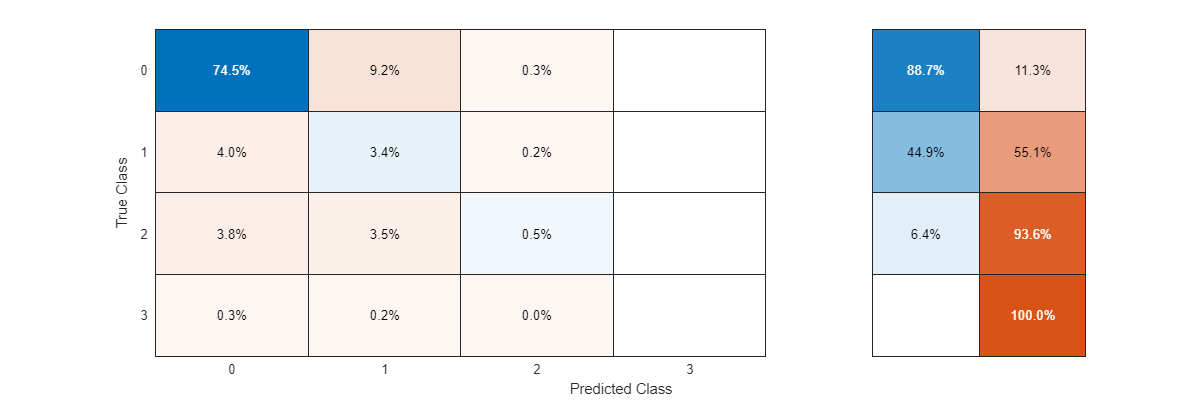

% Plot Confussion Matrix
fig = figure('Position', [0,0,1200,400]);
confusionchart(Validation_Data_Table.Risk_Label, y_valid_pred(:, 5), 'Normalization', 'total-normalized','RowSummary','row-normalized');

### Calculate Performance Metrics for Validation Dataset

% Misclassification Error
% Find wrong labels
for k = 1:5
    for i = 1:numel(y_valid)
        if y_valid_pred(i, k) ~= Validation_Data_Table.Risk_Label(i)
            y_valid_label_misclassifications(i, k) = 1;
        end
    end
end

% Find % of wrong classifications 
Classification_Error_valid = 100*sum(y_valid_label_misclassifications) / numel(y_valid);

Metrics = cat(1, Classification_Error_valid);
Metrics_Table = array2table(Metrics, 'RowNames', {'Classification Error [%]'}, 'VariableNames', {'Exponential', 'Squared Exponential', 'Matern32', 'Matern52','Rational Quadratic'});
disp(Metrics_Table)

                                Exponential    Squared Exponential    Matern32    Matern52    Rational Quadratic
                                ___________    ___________________    ________    ________    __________________

    Classification Error [%]      21.592             21.786            21.508      21.091           21.592      



### Predict for Test - Select Model with Best Metrics - Matern52

% Validation
y_test_pred = predict(gprMdl_4, x_test);

% Round to nearest integer
y_test_pred = round(y_test_pred);

### Calculate Performance Metrics for Test Dataset - Matern52

% Misclassification Error
% Find wrong labels
for i = 1:numel(y_test)
    if y_test_pred(i) ~= Validation_Data_Table.Risk_Label(i)
        y_test_label_misclassifications(i) = 1;
    end
end

% Find % of wrong classifications 
Classification_Error_test = 100*sum(y_test_label_misclassifications) / numel(y_test);

Metrics = cat(1, Classification_Error_test);
Metrics_Table = array2table(Metrics, 'RowNames', {'Classification Error [%]'}, 'VariableNames', {'Matern52'});
disp(Metrics_Table)

                                Matern52
                                ________

    Classification Error [%]     24.947 



### Plots on Test Dataset

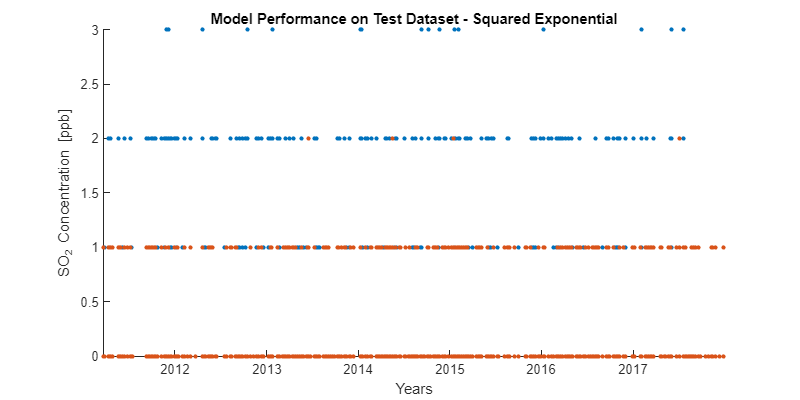

% Plot Actual Data vs Predicted Data
fig = figure('Position', [0,0,1200,400]);
scatter(t_test, y_test, 10, 'filled')
hold on
scatter(t_test, y_test_pred, 10, 'filled')
hold off
ylabel('SO_2 Concentration [ppb]')
xlabel('Years')
title('Model Performance on Test Dataset - Squared Exponential')

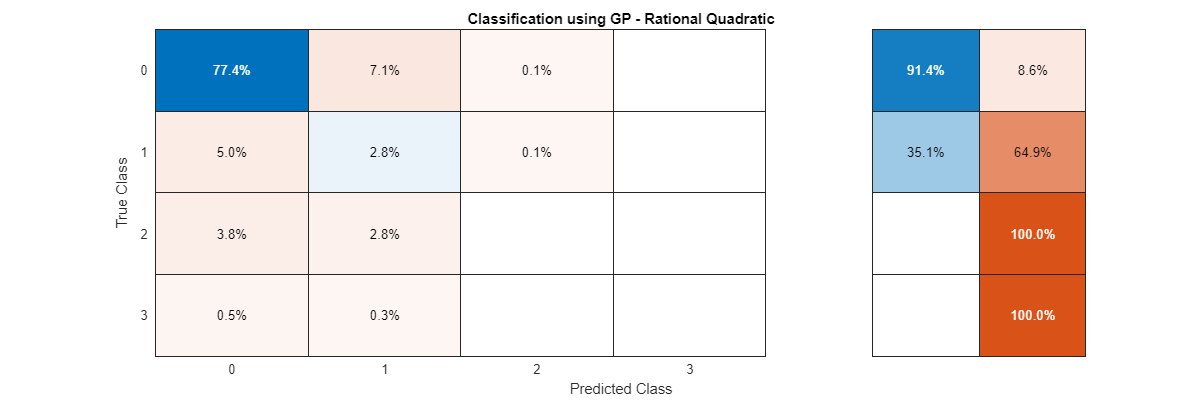

% Plot Confussion Matrix
fig = figure('Position', [0,0,1200,400]);
confusionchart(Testing_Data_Table.Risk_Label, y_test_pred, 'Normalization', 'total-normalized','RowSummary','row-normalized');
title('Classification using GP - Rational Quadratic')